# Lissajous animation

%{
    An animation for which y2 = cos(7*t) always, 
    but y1 = sin(k*t) where k increases from 1 to 21. 
    To avoid lissajous figures which are not closed, 
    at each stage of the animation, y1 is morphed linearly 
    from y1 = sin(k*t) to y1 = sin(k*t +t)
%}

clear, clc, close all

figure % Start with a new figure for your animation. 
% Animate the Lissajous curve using a double for loop. 

t = 0: 0.01:2*pi; % the angles
% Draw the first plot. 
y1 = sin(1*t);  y2 = cos(7*t);
my_color = [1/10 1-1/10 1 ]; % we'll animate the colors too. 
handle = plot(y1, y2, 'Color', my_color, 'LineWidth', 2);
axis([-1 1 -1 1 ])
axis square
set(gca,'fontsize', 20);
grid on, hold on
title('Lissajous Curve')
xlabel('y1= sin(1*t)')
ylabel('y2 = cos(7*t)')
pause(0.25) % wait 1/4 of a second

% start the animation loop
N=20

N = 20

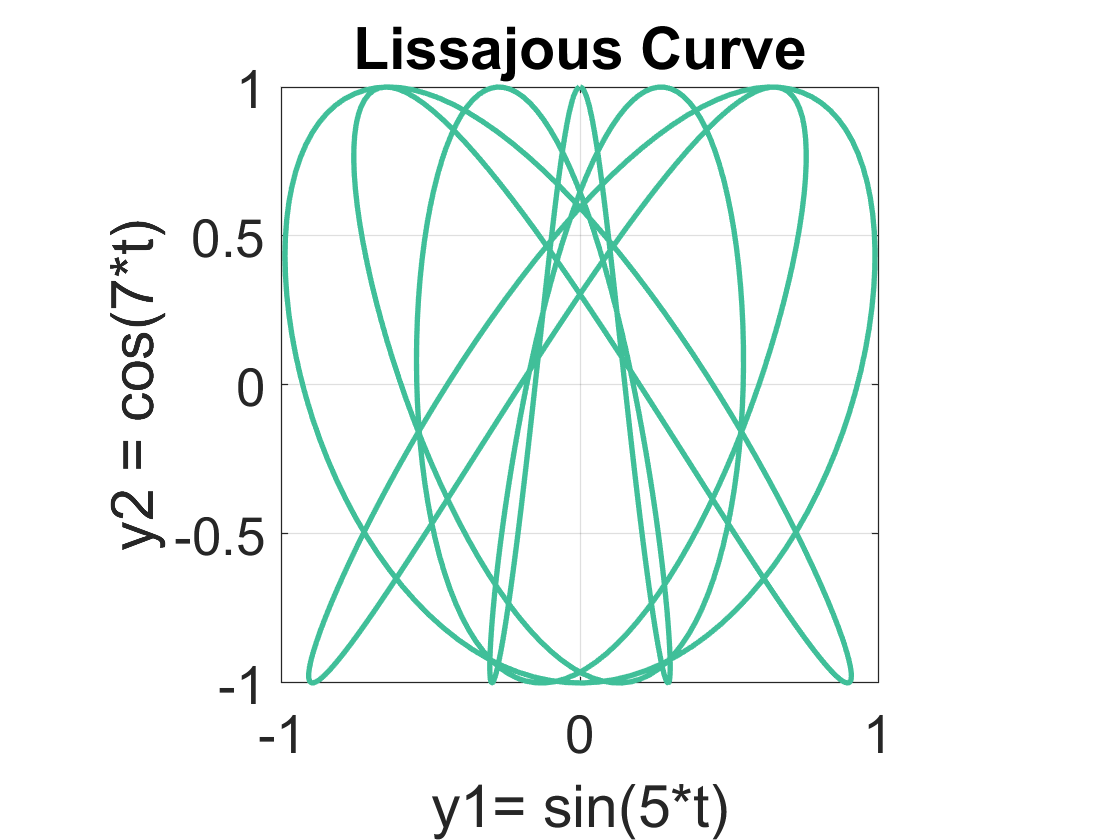

message = 'y1= sin(1*t)'

message = 'y1= sin(2*t)'

message = 'y1= sin(2*t)'

message = 'y1= sin(3*t)'

message = 'y1= sin(3*t)'

message = 'y1= sin(4*t)'

message = 'y1= sin(4*t)'

message = 'y1= sin(5*t)'

message = 'y1= sin(5*t)'

for k = 1:20 % The  angular frequency for the sine curve increases
    y1 = sin(k*t);  y2 = cos(7*t); % the cosine curve is always the same
    next_y1 = sin(k*t +t);
    message = sprintf('y1= sin(%d*t)', k)
    xlabel(message)
    for n = 0:N  % interpolate between successive frequencies (linear morphing)
        delete(handle)
        my_color = [k/N 1-k/N 1-n/N ];
        z = y1*(1-n/N) + next_y1 * -n/N;
        handle = plot(z, y2, 'Color', my_color, 'LineWidth', 2);
        pause(0.1)
    end
    message = sprintf('y1= sin(%d*t)', k+1)
    xlabel(message)
    pause(0.2)
end